## 2.2 definição variáveis do sistema.

clear all; close all; clc
nbit = 20000; % comprimento da sequência binária, valor variável
R = 1e6; % taxa de transmissão em bit/s
N = 16; % nº de amostras por símbolo
fa = N*R; % frequência de amostragem
DEPruido = -46; % DEP do ruído (bilateral) em dBm/Hz
Nfilt = 3; % ordem do filtro do receptor
Bfilt = 4e6; % frequência de corte do filtro do receptor
Ntempo = 32; % nº de símbolos a visualizar nos diagramas temporais
F=0.5; % fator de decaimento do cosseno elevado

## 3 - Transmição. Introdução de ruido

## Geração de sinal

%% geração do sinal
fprintf('Fig1:sequência original e com formatação cosseno-elevado\n')

Fig1:sequência original e com formatação cosseno-elevado


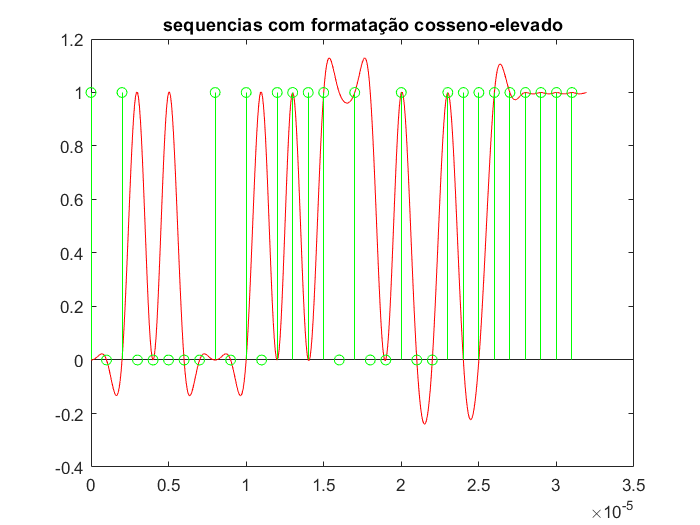

figure(1);
inf=randi([0 1],1,nbit); %sequencia binária com igual probabilidade para '0' e '1'
hold off;
[s_tx,t]=rcosflt(inf,R,N*R,'fir/normal',F);
plot(t(1:N*Ntempo),s_tx(1:N*Ntempo),'r');
title('sequencias com formatação cosseno-elevado');
hold on;
x=0:1/R:((Ntempo-1)/R);
stem(x,inf(1:Ntempo),'g');
hold off;

## 3.1 Potencia deo ruido a usar na simulação

Pruido_dBW=DEPruido-30+10*log10(fa);
Pruido=10^(Pruido_dBW/10);
fprintf('Potencia de ruido: %gW\n',Pruido)

Potencia de ruido: 0.401902W


fprintf('Potencia de ruido: %gdBW\n',Pruido_dBW)

Potencia de ruido: -3.9588dBW


## 3.2 Gerar ruido guassiano branco; por simulação obter a media e variancia

ruido=wgn(length(s_tx),1,Pruido_dBW); %funçao que gera o ruido gaussiano branco
fprintf('valor medio do ruido: %g volt \n', mean(ruido)) %media do ruido

valor medio do ruido: 0.0014854 volt 


fprintf('variancia do ruido: %g dBW\n',10*log10(var(ruido))) %variancia do ruido

variancia do ruido: -3.96292 dBW


%fprintf('desvio padrão: %g V\n',sqrt(ruido));

## 3.3 Histograma do ruido gerado normalizado, com 1000 intervalos de class e função densidade de probabilidade teorica

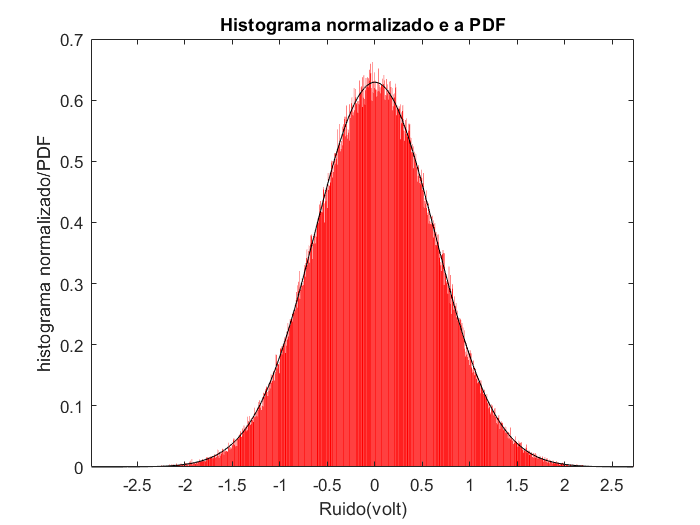

[n,x]=hist(ruido,1000); %n é o numero de contagens, com 1000 intervalos de classe
dx=abs(x(2)-x(1));
%Area total do grafico de barras é dividida pela sua área total
%area total do grafico de barras é 1(compativel com a definição de função densidade de probabilidade)
figure(2);
bar(x,n/(sum(n)*dx),'r');
xlabel('Ruido(volt)');ylabel('histograma normalizado/PDF');

%função de densidade probabilidade teorica
hold on;
sigma2_n=Pruido;
plot(x,1/sqrt(2*pi*sigma2_n)*exp(-x.^2/(2*sigma2_n)),'k');
title('Histograma normalizado e a PDF');
axis auto;

## 3.4 Trace um outro gráfico a DEP unilateral estimada por simulação e a correspondente DEP teórica. 

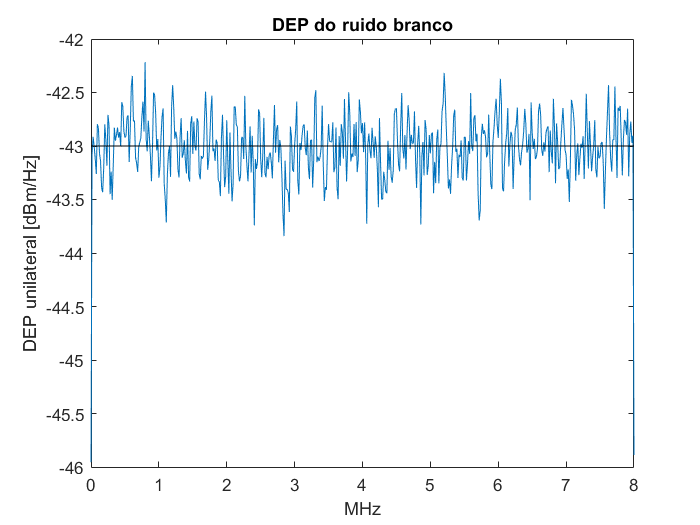

windowL_n=1024; % comprimento do segmento
[Prr,f]=pwelch(ruido,windowL_n,0,windowL_n,fa);
figure(3);
plot(f/1e6, 10*log10(Prr)+30, f/1e6,(DEPruido+3)*ones(size(f)),'k');
title('DEP do ruido branco');
xlabel('MHz'); ylabel('DEP unilateral [dBm/Hz]');

## 4. Recetor

## 4.1 Filtragem a)

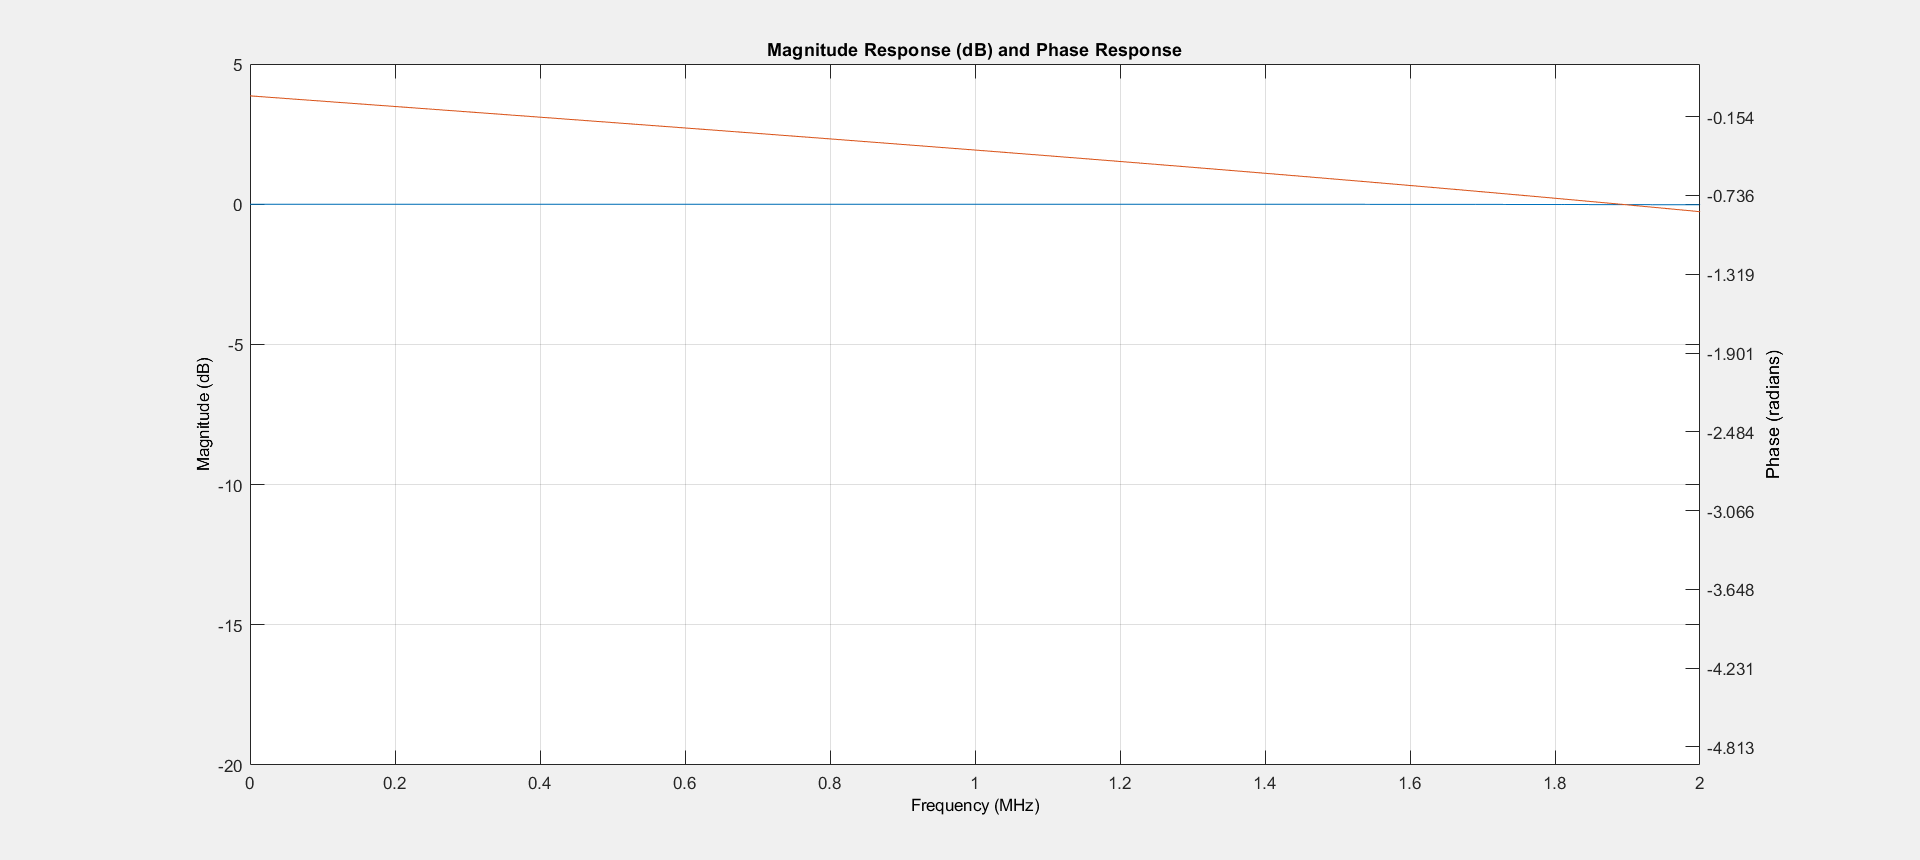

[b,a]=butter(Nfilt,Bfilt/(fa/2)); %Nfilt=>ordem do filtro no recetor; Bfilt=>freq de corte do filtro no recetor
h1 = fvtool(b,a,'Analysis','freq');
set(h1,'Fs',fa); zoom(h1,'x',[0 2]); zoom(h1,'y',[-20 5]); 

## b)

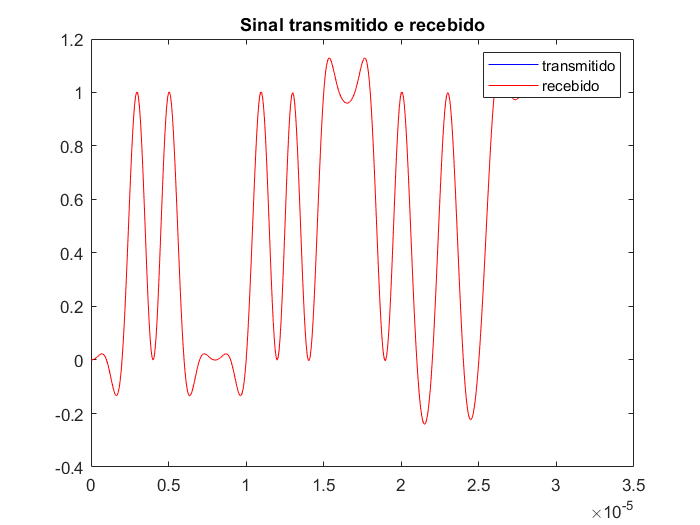

s_tx;%sinal transmitido
s_rx = s_tx + ruido;            % sinal antes do filtro
s_filt_rx = filter(b,a,s_rx);% sinal apos o filtro
s_filt_tx=filter(b,a,s_tx);%sinal transmitido (sem ruido) filtrado
%ver se o sinal fica pior do q o ruido
figure(4);
plot(t(1:N*Ntempo),s_tx(1:N*Ntempo),'b');
hold on;
plot(t(1:N*Ntempo),s_rx(1:N*Ntempo),'m');
title('Sinal transmitido e recebido');
legend('transmitido','recebido');

figure(7);
plot(t(1:N*Ntempo),s_tx(1:N*Ntempo),'b');
hold on;
plot(t(1:N*Ntempo),s_tx(1:N*Ntempo),'r');
title('Sinal transmitido e recebido');
legend('transmitido','recebido');

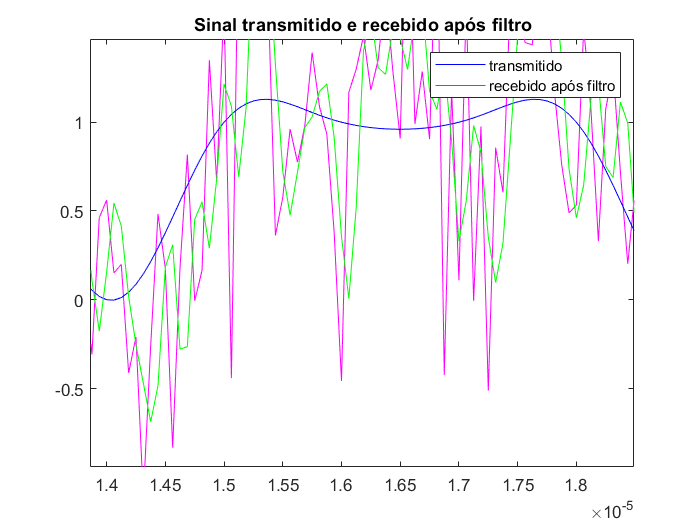


figure(5);
plot(t(1:N*Ntempo),s_tx(1:N*Ntempo),'b');
hold on;
plot(t(1:N*Ntempo),s_filt_rx(1:N*Ntempo),'g');
title('Sinal transmitido e recebido após filtro');
legend('transmitido','recebido após filtro');


figure(6);
plot(t(1:N*Ntempo),s_tx(1:N*Ntempo),'b');
hold on;
plot(t(1:N*Ntempo),s_filt_tx(1:N*Ntempo),'y');
title('Sinal transmitido (sem ruido) filtrado');
legend('transmitido sem ruido filtrado','recebido');

## 4.1 b) Diagrama de Olho

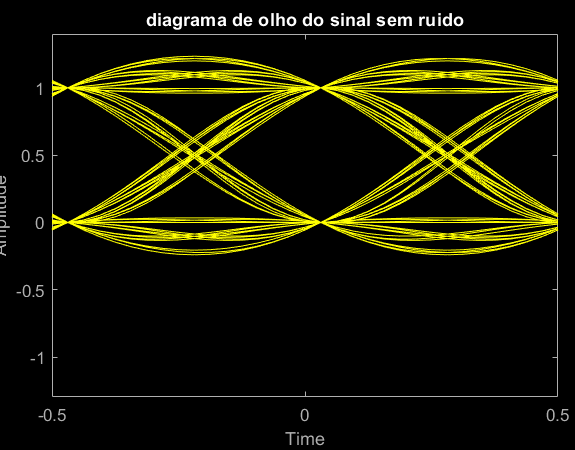

s_filt_tx = filter(b,a,s_tx);      
 eyediagram(s_filt_tx(1:256*N), 2*N);
 title('diagrama de olho do sinal sem ruido');

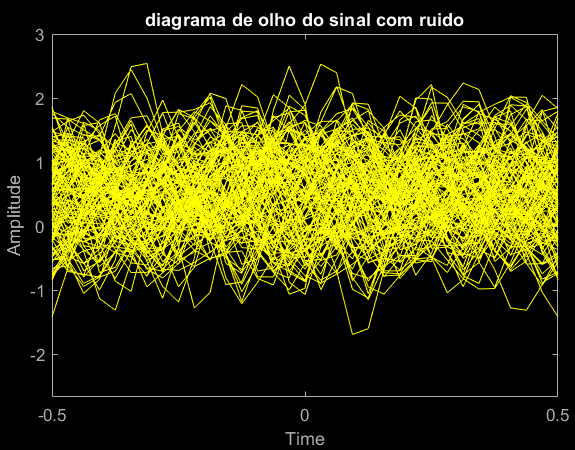

 eyediagram(s_filt_rx(1:256*N), 2*N);
 title('diagrama de olho do sinal com ruido');

## 4.2 Amostragem

## a)!ACABAR!

 [corr,atraso]=correlacao(inf,s_filt_tx,N,64,16);
 fprintf('Atraso do sinal no recetor depois de filtrado: %g\n',atraso);

Atraso do sinal no recetor depois de filtrado: 49


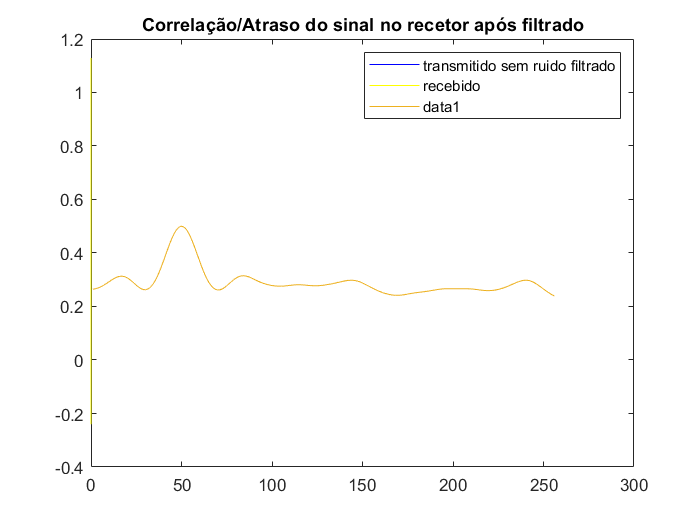

 figure(6);
 plot(corr);
 title('Correlação/Atraso do sinal no recetor após filtrado');

 %64 amostras que estamos a atrasar

## b)

 % Histograma Condicionado ao "0"
s_amost_0=s_amost(find(inf==0));% Amostras relativo aos “0”s

Unrecognized function or variable 's_amost'.

[n0, x0] = hist(s_amost_0,100);
dx0 = abs(x0(2)-x0(1));
bar(x0,n0/(sum(n0)*dx0),'b');
hold on
% Histograma Condicionado ao "1"
s_amost_1=s_amost(find(inf==1)); % Amostras relativo aos “1”s
[n1, x1] = hist(s_amost_1,1000);
dx1 = abs(x1(2)-x1(1));
bar(x1,n1/(sum(n1)*dx1),'r');
title('Histogramas à entrada do circuito decisão (condicionado ao “0” e “1”)');
xlabel('tensão [volt]'); ylabel ('Frequência Relativa Normalizada')
hold off